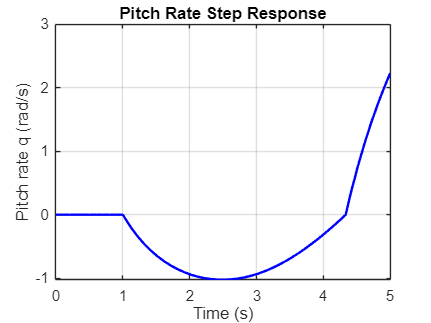

clear
clc


% 0 Controller value

Kp_1 = -97;

% 1 Run model
open('Pitch_Rate_Damper.slx')
out = sim('Pitch_Rate_Damper.slx');

% 2 Extract time and signal data
t = out.q.Time;      % Time vector
q = out.q.Data;      % Pitch rate (rad/s)

% 3 Compute step response characteristics

% Plot for verification
figure;
plot(t, q, 'b', 'LineWidth', 1.5);
xlabel('Time (s)');
ylabel('Pitch rate q (rad/s)');
title('Pitch Rate Step Response');
grid on;


% Compute step response characteristics
info = stepinfo(q, t);
disp('Step Response Characteristics:');

Step Response Characteristics:


disp(info);

         RiseTime: 0.5275
    TransientTime: 4.9740
     SettlingTime: 4.9822
      SettlingMin: 2.0251
      SettlingMax: 2.2288
        Overshoot: 0
       Undershoot: 45.8764
             Peak: 2.2288
         PeakTime: 5

